# EEG Preprocessing

## 1. Load Data 

*eeg_raw*: contains data of 12 eeg channels + 1 ecg channel

subject = input('Subject: '); 
filetype = input('File Type: ', 's');

channelName = {'O1', 'O2', 'Fp1', 'Fp2', 'P7', 'P8', ...
               'P3', 'P4', 'F3', 'F4', 'T7', 'T8', 'ECG'};

if strcmp(filetype, 'edf')
    file = sprintf('C:/Users/Natchira/Documents/M.eng (from hp)/Thesis/OpenViBE/Vertcat_Data/variable_Subject%d.mat', subject);
else
    file = sprintf('C:/Users/Natchira/Documents/M.eng (from hp)/Thesis/OpenViBE/Vertcat_Data/variable_Subject%d_csv.mat', subject);
end

% Generate variable names for y1 to y13
varsToLoad = {'data_path', 'filename', 'fs', 'numChannel', 'numSamples'};
for i = 1:13
    if strcmp(filetype, 'edf')
        varsToLoad{end+1} = sprintf('y%d', i);
    else
        varsToLoad{end+1} = sprintf('y%d_csv', i);
    end
end

% Load the specified variables
dataStruct = load(file, varsToLoad{:});
fs = dataStruct.fs;

% Assuming raw_eeg data is stored in y1 to y13 variables in the .mat file
eeg_raw = zeros(dataStruct.numSamples, length(channelName)); % Preallocate based on your data structure
for i = 1:13
    if strcmp(filetype, 'edf')
        channelData = dataStruct.(sprintf('y%d', i)); % Dynamically access each channel's data
    else
        channelData = dataStruct.(sprintf('y%d_csv', i));
    end
    eeg_raw(:, i) = channelData;
end

## 2. Crop Data (70 minutes)

Pre-driving (5 minutes) + Driving (60 minutes) + Post-driving (5 minutes)

*raw_eeg_crop*: 70-minute data of 12 eeg channels + 1 ecg channels

% crop data
start_second = [61 61 34 88 37 52 41.5 51 35.5 16.5 160 35.5 53 29 20];
end_second = start_second + 4200; % 70 minutes in seconds
start_index = round(start_second(subject) * dataStruct.fs) + 1;
end_index = round(end_second(subject) * dataStruct.fs);

eeg_raw_crop = eeg_raw(start_index:end_index, :);

datalength = size(eeg_raw_crop, 1);

numSamples = fs*60*70;

### 3.2 Check FFT, PSD (raw)

- **Specify the time frame & channel**

% Create a time vector (in seconds)
t = (0:dataStruct.numSamples-1) / fs; % Time vector of the whole data

% Define the time interval
startTime = input('Start Time: ');
endTime = input('End Time: ');

channel = input('Channel: ');

- **Plot bandpass data, PSD, FFT of the specific time frame & channel**

% Calculate the corresponding indices
startIndex = startTime * fs;
endIndex = endTime * fs - 1;

% Extract the relevant portion of the data
dataSegment = eeg_raw_crop(startIndex:endIndex, channel);

% Create a time vector for the plot
timeVector = linspace(startTime, endTime, length(dataSegment));


% Plot the data
figure;
subplot(3,1,1);
plot(timeVector, dataSegment);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(sprintf('%s: eeg raw crop (%d - %d seconds)', channelName{channel}, startTime, endTime));

% power spectral density
subplot(3,1,2);
pspectrum(dataSegment,fs)

% FFT
% Filtering --> FFT

y_fft = fft(dataSegment);
T = 1/fs; % sampling period
% L = fs*2; % length of signal
L = length(dataSegment)

L = 30720

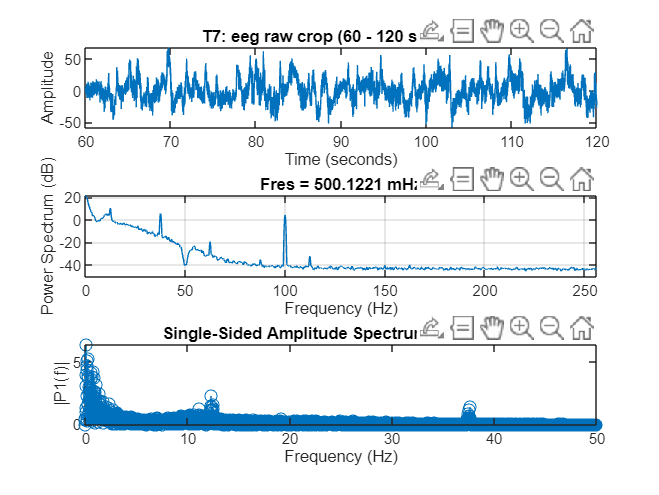

P2_f = abs(y_fft/L);
P1_f = P2_f(1:L/2+1);
P1_f(2:end-1) = 2*P1_f(2:end-1);
f = fs *(0:(L/2))/L;

subplot(3,1,3);
stem(f,P1_f);
xlim([0 50])
title("Single-Sided Amplitude Spectrum of raw data");
xlabel('Frequency (Hz)');
ylabel('|P1(f)|');

##  3. Filter

### 3.1 Bandpass Filter (0.5-40 Hz)

***eeg_bandpass*****: **

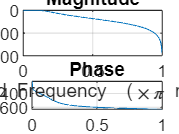

% Filter order
order = 3;

% Cutoff frequencies (in Hz)
low_freq = 0.5;
high_freq = 40;

% Calculate normalized cutoff frequencies
Wn = [low_freq, high_freq] / (dataStruct.fs/2);

% Design bandpass Butterworth filter
[b, a] = butter(order, Wn, 'bandpass');

freqz(b,a)


eeg_bandpass = filtfilt(b, a, eeg_raw_crop);



***eeg_lowpass & eeg_lowhighpass***

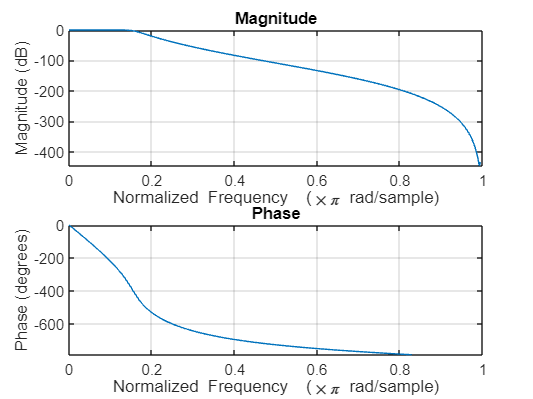

%% Low Pass Filter 
% Order
lowpass_order = 9;

% Cutoff frequencies (Hz)
lowpass_freq = 40;

% Calculate normalized cutoff frequencies
lowpass_Wn = lowpass_freq / (fs/2);

% Design lowpass Butterworth filter
[x, y] = butter(lowpass_order, lowpass_Wn, 'Low');

freqz(x, y)


eeg_lowpass = filtfilt(x, y, eeg_raw_crop);


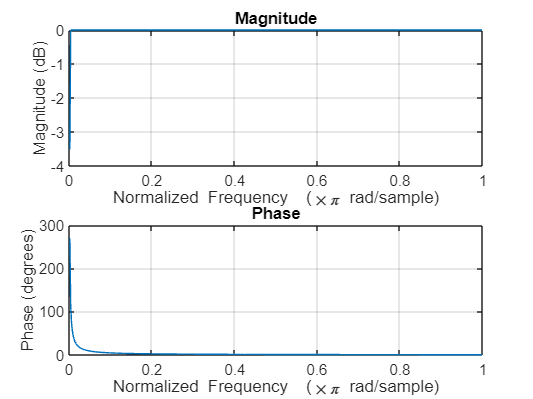

%% High Pass Filter

% Order
highpass_order = 6;

% Cutoff frequencies (Hz)
highpass_freq = 0.5;

% Calculate normalized cutoff frequencies
highpass_Wn = highpass_freq / (fs/2);

% Design lowpass Butterworth filter
[w, z] = butter(highpass_order, highpass_Wn, 'High');

freqz(w, z)


eeg_lowhighpass = filtfilt(w, z, eeg_lowpass);


***eeg_bandpass_notch***

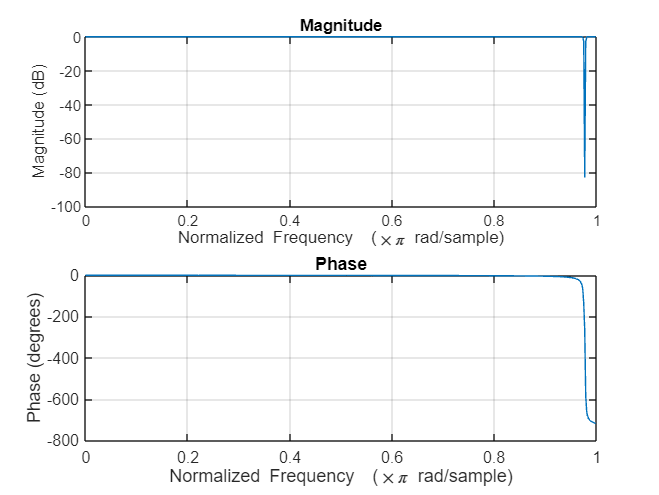

% Filter order
eeg_bandpass_notch = eeg_bandpass;

order = 3;

n = 0;
while 50*(n+1) < 256
    notch_freq = 50*(n+1); % Target notch frequency
    low_notch_freq = notch_freq - 0.5;
    high_notch_freq = notch_freq + 0.5;
    Wn_notch = [low_notch_freq, high_notch_freq] / (fs/2);
    [d, c] = butter(order, Wn_notch, 'stop');
    freqz(d, c)
    eeg_bandpass_notch = filtfilt(d, c, eeg_bandpass_notch);
    n = n+1;
end

order = 5

order = 5

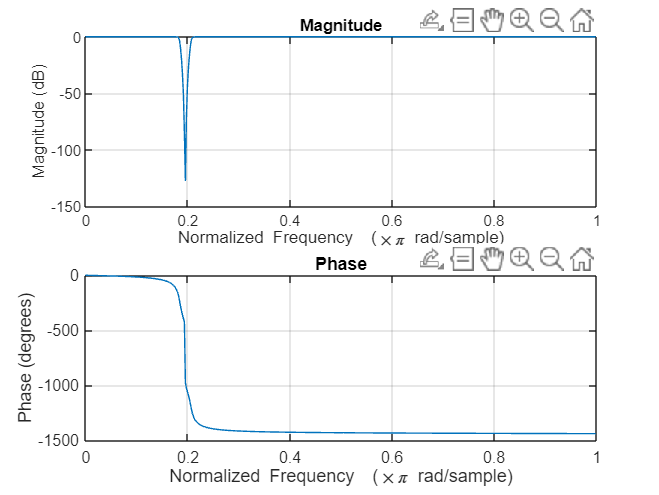


low_notch50_freq = 50-3;
high_notch50_freq = 50+3;
Wn_notch50 = [low_notch50_freq, high_notch50_freq] / (fs/2);

[e, f] = butter(order, Wn_notch50, 'stop');
freqz(e, f)

### 3.2 Check FFT, PSD

- **Specify the time frame & channel**

% Create a time vector (in seconds)
t = (0:dataStruct.numSamples-1) / fs; % Time vector of the whole data

% Define the time interval
startTime = input('Start Time: ');
endTime = input('End Time: ');

channel = input('Channel: ');

- **Plot bandpass data, PSD, FFT of the specific time frame & channel**

% Calculate the corresponding indices
startIndex = startTime * fs;
endIndex = endTime * fs - 1;

% Extract the relevant portion of the data
dataSegment = eeg_bandpass(startIndex:endIndex, channel);

% Create a time vector for the plot
timeVector = linspace(startTime, endTime, length(dataSegment));


% Plot the data
figure;
subplot(3,1,1);
plot(timeVector, dataSegment);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(sprintf('%s: eeg bandpass (%d - %d seconds)', channelName{channel}, startTime, endTime));

% power spectral density
subplot(3,1,2);
pspectrum(dataSegment,fs)

% FFT
% Filtering --> FFT

y_fft = fft(dataSegment);
T = 1/fs; % sampling period
% L = fs*2; % length of signal
L = length(dataSegment)
P2_f = abs(y_fft/L);
P1_f = P2_f(1:L/2+1);
P1_f(2:end-1) = 2*P1_f(2:end-1);
f = fs *(0:(L/2))/L;

subplot(3,1,3);
stem(f,P1_f);
xlim([0 50])
title("Single-Sided Amplitude Spectrum of raw data");
xlabel('Frequency (Hz)');
ylabel('|P1(f)|');

### 3.2 Check FFT, PSD (after notch)

- **Specify the time frame & channel**

% Create a time vector (in seconds)
t = (0:dataStruct.numSamples-1) / fs; % Time vector of the whole data

% Define the time interval
startTime = input('Start Time: ');
endTime = input('End Time: ');

channel = input('Channel: ');

- **Plot bandpass data, PSD, FFT of the specific time frame & channel**

% Calculate the corresponding indices
startIndex = startTime * fs;
endIndex = endTime * fs - 1;

% Extract the relevant portion of the data
dataSegment = eeg_bandpass_notch(startIndex:endIndex, channel);

% Create a time vector for the plot
timeVector = linspace(startTime, endTime, length(dataSegment));


% Plot the data
figure;
subplot(3,1,1);
plot(timeVector, dataSegment);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(sprintf('%s: eeg bandpass+notch (%d - %d seconds)', channelName{channel}, startTime, endTime));

% power spectral density
subplot(3,1,2);
pwelch(dataSegment)

% FFT
% Filtering --> FFT

y_fft = fft(dataSegment);
T = 1/fs; % sampling period
% L = fs*2; % length of signal
L = length(dataSegment)

L = 15360

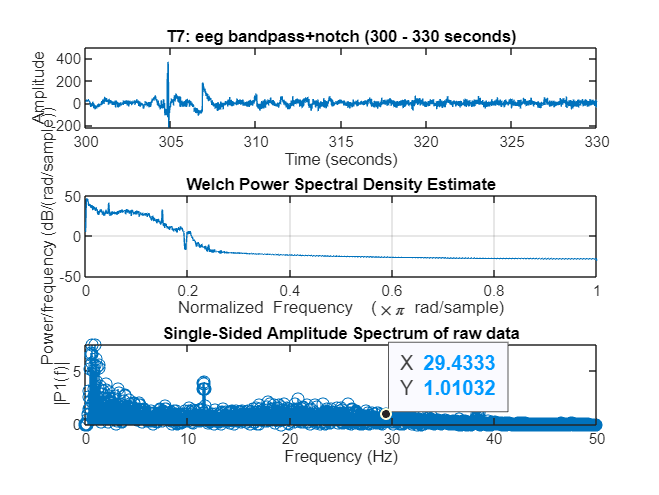

P2_f = abs(y_fft/L);
P1_f = P2_f(1:L/2+1);
P1_f(2:end-1) = 2*P1_f(2:end-1);
f = fs *(0:(L/2))/L;

subplot(3,1,3);
stem(f,P1_f);
xlim([0 50])
title("Single-Sided Amplitude Spectrum of raw data");
xlabel('Frequency (Hz)');
ylabel('|P1(f)|');

#### Plot Data 

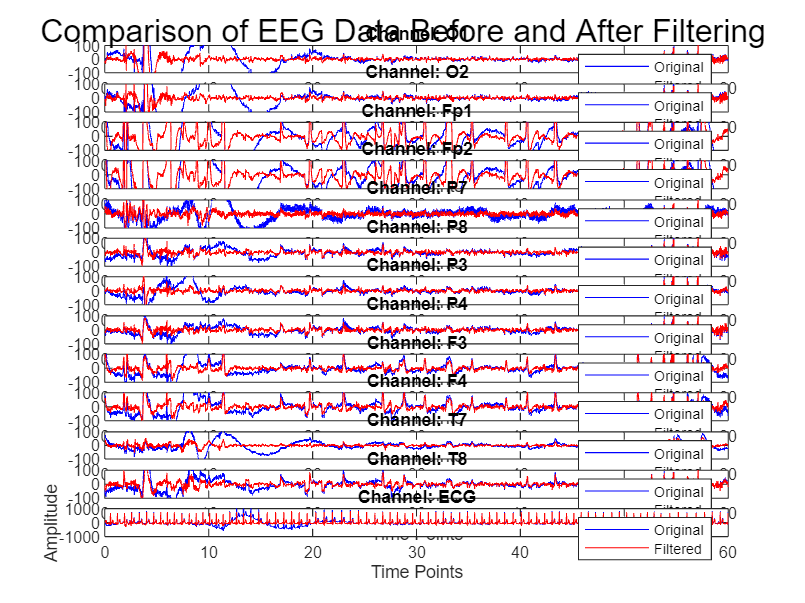

% Number of channels
numChannels = size(eeg_raw_crop, 2);

% Create a time vector (in seconds)
timeVector = (0:datalength-1)/dataStruct.fs;

% Create a figure to hold all subplots
figure;

% Loop through each channel to create a subplot
for i = 1:numChannels
    subplot(numChannels, 1, i); % Adjust layout to fit your screen or preferences
    plot(timeVector, eeg_raw_crop(:, i), 'b'); % Plot original data in blue
    hold on;
    plot(timeVector, eeg_bandpass(:, i), 'r'); % Plot filtered data in red
    hold off;
    legend('Original', 'Filtered');
    title(sprintf('Channel: %s', channelName{i})); % Use channel names for titles
    xlabel('Time Points');
    xlim([0 60])
    if i == 13
        ylim([-1000 1000])
    else
        ylim([-100 100])
    end
end

% Enhance layout
ylabel('Amplitude', 'Units', 'Normalized', 'Position', [-0.07, 0.5, 0]);
set(gca, 'YTickLabelMode', 'auto');
sgtitle('Comparison of EEG Data Before and After Filtering'); % Super title for the figure

### 3.2 Check FFT, PSD

- **Specify the time frame & channel**

% Create a time vector (in seconds)
t = (0:dataStruct.numSamples-1) / fs; % Time vector of the whole data

% Define the time interval
startTime = input('Start Time: ');
endTime = input('End Time: ');

channel = input('Channel: ');

- **Plot bandpass data, PSD, FFT of the specific time frame & channel**

% Calculate the corresponding indices
startIndex = startTime * fs;
endIndex = endTime * fs - 1;

% Extract the relevant portion of the data
dataSegment = eeg_bandpass(startIndex:endIndex, channel);

% Create a time vector for the plot
timeVector = linspace(startTime, endTime, length(dataSegment));


% Plot the data
figure;
subplot(3,1,1);
plot(timeVector, dataSegment);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(sprintf('%s: eeg bandpass (%d - %d seconds)', channelName{channel}, startTime, endTime));

% power spectral density
subplot(3,1,2);
pspectrum(dataSegment,fs)

% FFT
% Filtering --> FFT

y_fft = fft(dataSegment);
T = 1/fs; % sampling period
% L = fs*2; % length of signal
L = length(dataSegment)

L = 30720

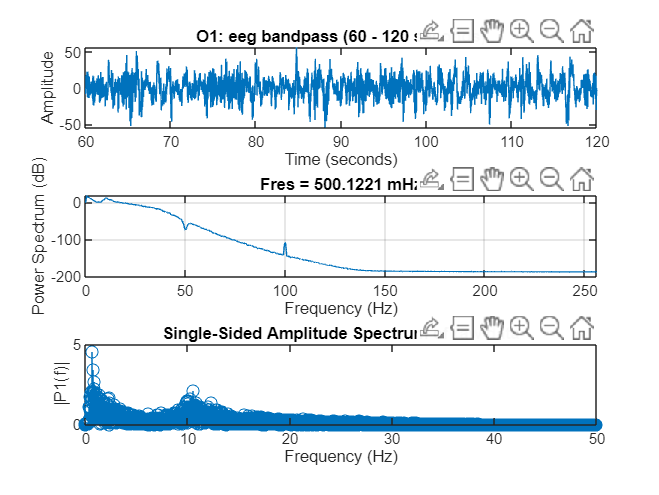

P2_f = abs(y_fft/L);
P1_f = P2_f(1:L/2+1);
P1_f(2:end-1) = 2*P1_f(2:end-1);
f = fs *(0:(L/2))/L;

subplot(3,1,3);
stem(f,P1_f);
xlim([0 50])
title("Single-Sided Amplitude Spectrum of raw data");
xlabel('Frequency (Hz)');
ylabel('|P1(f)|');

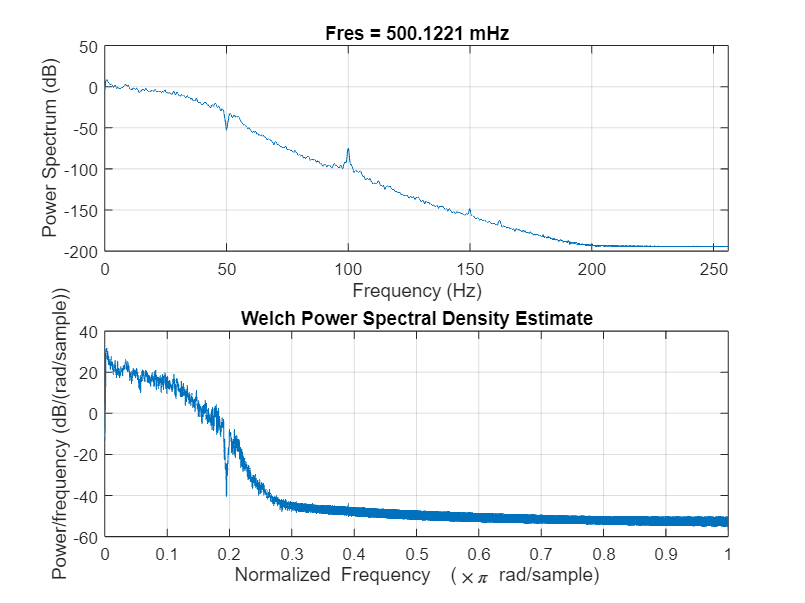

figure;
subplot(2,1,1);
pspectrum(dataSegment,fs)

subplot(2,1,2);
pwelch(dataSegment, [])

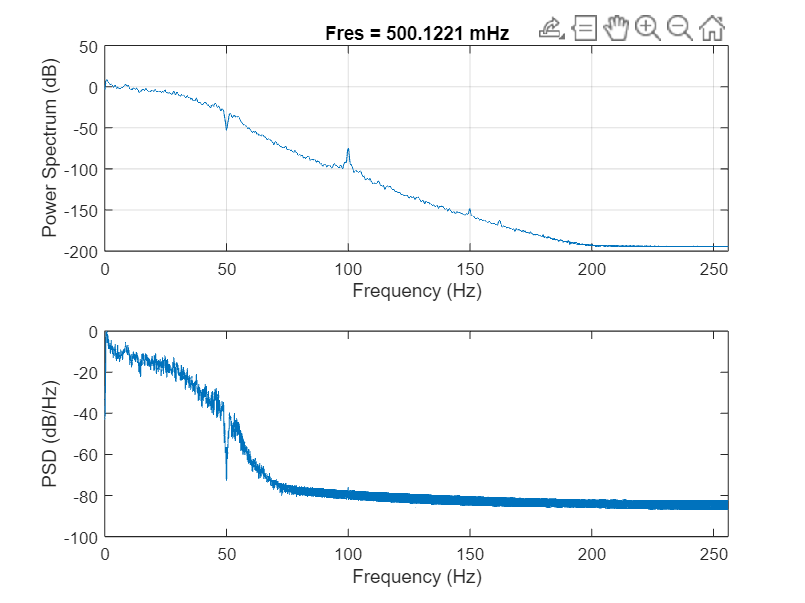

figure;

subplot(2,1,1);
pspectrum(dataSegment,fs)

subplot(2,1,2);
% [pxx,f] = pwelch(dataSegment,500,300,500,fs);
[pxx,f] = pwelch(dataSegment,[],[],[],fs,'centered','power');

plot(f,10*log10(pxx))
xlim([0 256])

xlabel('Frequency (Hz)')
ylabel('PSD (dB/Hz)')

- **generate the figures of bandpass data, PSD, FFT for each minute, each channel, each subject**

70 minutes *(pre-driving+driving+post-driving) ** 13 channels *(12 EEG + 1 ECG) * *15 subjects

Total no. of figures: 13650

% Assuming fs, eeg_bandpass, and channelName are already defined

numChannels = size(eeg_bandpass, 2); % Number of channels
totalSeconds = size(eeg_bandpass, 1) / fs; % Total duration of the dataset in seconds
minutesInDataset = floor(totalSeconds / 60); % Total full minutes in the dataset

% Specify the folder to save the images
rootFolder = 'C:/Users/Natchira/Documents/M.Eng Thesis/MATLAB Drive/All data/Subject02'; % Update this path to your desired folder
if ~exist(rootFolder, 'dir')
    mkdir(rootFolder); % Create the folder if it doesn't exist
end

for channel = 1:numChannels % Loop through each channel
    % Create or check for a subfolder for the current channel
    channelFolder = fullfile(rootFolder, sprintf('Channel_%s', channelName{channel}));
    if ~exist(channelFolder, 'dir')
        mkdir(channelFolder);
    end
    
    for minute = 0:(minutesInDataset-1) % Loop through each minute
        startTime = minute * 60; % Start time in seconds for the current minute
        endTime = startTime + 60; % End time in seconds for the current minute

        % Calculate the corresponding indices
        startIndex = startTime * fs + 1;
        endIndex = endTime * fs;

        % Extract the relevant portion of the data for the current channel
        dataSegment = eeg_bandpass(startIndex:endIndex, channel);

        % Create a time vector for the plot
        timeVector = linspace(startTime, endTime, length(dataSegment));

        % Plot the data
        figure('visible','off'); % Create a new figure in the background
        subplot(3,1,1);
        plot(timeVector, dataSegment);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title(sprintf('%s: EEG Bandpass (%d - %d seconds)', channelName{channel}, startTime, endTime));

        % Power spectral density
        subplot(3,1,2);
        pspectrum(dataSegment, fs);

        % FFT
        y_fft = fft(dataSegment);
        T = 1/fs; % Sampling period
        L = length(dataSegment); % Length of signal
        P2_f = abs(y_fft/L);
        P1_f = P2_f(1:L/2+1);
        P1_f(2:end-1) = 2*P1_f(2:end-1);
        f = fs * (0:(L/2)) / L;

        subplot(3,1,3);
        stem(f, P1_f);
        xlim([0 50]);
        title("Single-Sided Amplitude Spectrum of the data");
        xlabel('Frequency (Hz)');
        ylabel('|P1(f)|');

        % Save the figure
        outputFilename = sprintf('%s_%d-%dseconds.png', channelName{channel}, startTime, endTime);
        saveas(gcf, fullfile(channelFolder, outputFilename));
        close(gcf); % Close the figure after saving to free up system resources
    end
end

### 4. Artifact Subspace Reconstruction (ASR)

- **Export EEG data (eeg_bandpass) to EEGLAB**

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\Natchira\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.3 to the path
EEGLAB: adding "Fileio" v20240111 to the path
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit) - new version 5.4 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt) - new version 2.8 available
EEGLAB: adding "neuroscanio" v1.8 (see >> help eegplugin_neuroscanio)


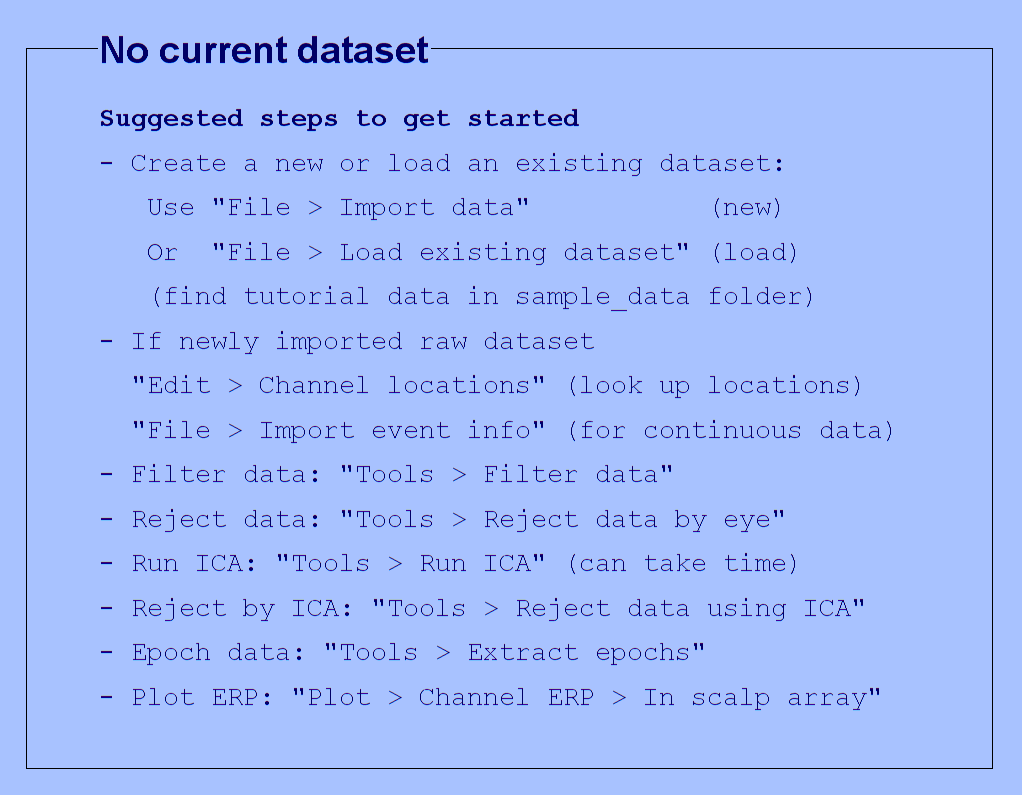

eeglab;

% eeg_bandpass_eeglab = eeg_bandpass';
eeg_bandpass_eeglab = eeg_bandpass(:, 1:12)'; % create array with only EEG data (channels x datapoints)

eeg_lowhighpass_eeglab = eeg_lowhighpass(:, 1:12)';

- **export eeg_bandpass to EEGLAB**

% Load your data into MATLAB
% Assuming your data is in a variable named 'combinedData'
% combinedData should be a 2D array of size [channels x time points]

% Set EEG parameters
EEG = eeg_emptyset(); % Create an empty EEG structure
EEG.data = eeg_bandpass_eeglab; % Your 2D array [channels x time points]
EEG.nbchan = size(EEG.data, 1); % Number of channels
EEG.pnts = size(EEG.data, 2); % Number of time points
EEG.srate = 512; % Sampling rate in Hz, replace with your actual sampling rate
EEG.times = (0:EEG.pnts-1) / EEG.srate; % Time vector (in seconds)
EEG.trials = 1; % Number of epochs (set to 1 for continuous data)
EEG.xmin = EEG.times(1); % Start time
EEG.xmax = EEG.times(end); % End time

% Optionally, set channel information if available
% EEG.chanlocs = ...

% Update EEGLAB with the new dataset
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);

Creating a new ALLEEG dataset 1


EEG = eeg_checkset(EEG);

% Now your data is loaded into EEGLAB, and you can use EEGLAB functions to
% process it

- **import eeg_bandpass_asr to matlab workspace**

eeg_bandpass_asr = EEG.data; % This will be a matrix of size [channels x samples]
eeg_bandpass_asr = eeg_bandpass_asr';

- **export eeg_lowhighpass to EEGLAB**

% Import low&high pass eeg data to eeglab
EEG = eeg_emptyset(); % Create an empty EEG structure
EEG.data = eeg_lowhighpass_eeglab; % Your 2D array [channels x time points]
EEG.nbchan = size(EEG.data, 1); % Number of channels
EEG.pnts = size(EEG.data, 2); % Number of time points
EEG.srate = 512; % Sampling rate in Hz, replace with your actual sampling rate
EEG.times = (0:EEG.pnts-1) / EEG.srate; % Time vector (in seconds)
EEG.trials = 1; % Number of epochs (set to 1 for continuous data)
EEG.xmin = EEG.times(1); % Start time
EEG.xmax = EEG.times(end); % End time

% Optionally, set channel information if available
% EEG.chanlocs = ...

% Update EEGLAB with the new dataset
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG);

Creating a new ALLEEG dataset 1


EEG = eeg_checkset(EEG);

- **import eeg_lowhighpass_asr to matlab workspace**

eeg_lowhighpass_asr = EEG.data; % This will be a matrix of size [channels x samples]
eeg_lowhighpass_asr = eeg_lowhighpass_asr';

- **Add channel locations**

- **Perform ASR5 in EEGLAB **(correlation 0.7, no removal, no ECG)

(ASR4 = correlation 0.7, no removal)

(ASR5 = correlation 0.7, no removal, no ECG)

% % Apply ASR with default parameters or customize as needed

The function clean_rawdata has been deprecated and is only kept for backward
compatibility. Use the clean_artifacts function instead.
Detecting flat line...
Applying highpass filter...
Scanning for bad channels...
clean_channel:   1/839 blocks, 0.3 minutes remaining.
clean_channel:   2/839 blocks, 0.2 minutes remaining.
clean_channel:   3/839 blocks, 0.1 minutes remaining.
clean_channel:   4/839 blocks, 0.1 minutes remaining.
clean_channel:   5/839 blocks, 0.1 minutes remaining.
clean_channel:   6/839 blocks, 0.1 minutes remaining.
clean_channel:   7/839 blocks, 0.1 minutes remaining.
clean_channel:   8/839 blocks, 0.1 minutes remaining.
clean_channel:   9/839 blocks, 0.1 minutes remaining.
clean_channel:  10/839 blocks, 0.1 minutes remaining.
clean_channel:  11/839 blocks, 0.1 minutes remaining.
clean_channel:  12/839 blocks, 0.1 minutes remaining.
clean_channel:  13/839 blocks, 0.1 minutes remaining.
clean_channel:  14/839 blocks, 0.1 minutes remaining.
clean_channel:  15/839 blocks,

% EEG = clean_rawdata(EEG, [], [], [], [], [], []);
% 
% % Explanation of parameters (check the function help for more details):
% % EEG: input EEG structure
% % 5: maximum allowable standard deviation for bad channel detection (-1 to skip)
% % -1: flat line detection threshold in seconds (-1 to skip)
% % -1: minimum correlation (-1 to skip)
% % -1: line noise criterion (-1 to skip)
% % -1: high-pass filter settings (-1 to skip)
% % -1: burst criterion, standard deviation threshold (-1 to skip)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% subject 7: 0.7  correlation, no remove
% subject 7: 0.7  correlation, no remove, no Fp1Fp2

- **Save the EEG data after performing ASR**

% % Save the cleaned EEG dataset
% EEG = pop_saveset(EEG, 'filename', 'cleaned_dataset.set', 'filepath', '/path/to/your/data/');

- **Import EEG data from EEGLAB to Matlab**

eeg_bandpass_asr = EEG.data; % This will be a matrix of size [channels x samples]
eeg_bandpass_asr = eeg_bandpass_asr';

eeg_lowhighpass_asr

% if size(eeg_bandpass_asr, 2) == 11
%     % Assuming eeg_bandpass is 2150400x13 and eeg_bandpass_asr is 2150400x11
% 
%     % Convert eeg_bandpass_asr to double for consistency if necessary
%     eeg_bandpass_asr = double(eeg_bandpass_asr);
% 
%     % Preallocate a new array with zeros for the final array
%     eeg_bandpass_asr_updated = zeros(size(eeg_bandpass_asr, 1), 13);
% 
%     % Copy existing columns from eeg_bandpass_asr to the new array
%     eeg_bandpass_asr_updated(:, [1:2, 5:13]) = eeg_bandpass_asr(:, 1:11);
% 
%     % Insert columns 3 and 4 from eeg_bandpass into their respective positions
%     eeg_bandpass_asr_updated(:, 3) = eeg_bandpass(:, 3);
%     eeg_bandpass_asr_updated(:, 4) = eeg_bandpass(:, 4);
% 
%     % If you want to convert back to single after operation
%     % eeg_bandpass_asr_updated = single(eeg_bandpass_asr_updated);
% end

- **generate the figures of bandpass data, PSD, FFT for each minute, each channel, each subject**

70 minutes *(pre-driving+driving+post-driving) ** 13 channels *(12 EEG + 1 ECG) * *15 subjects

Total no. of figures: 13650

% Assuming fs, eeg_bandpass, and channelName are already defined

numChannels = size(eeg_bandpass_asr, 2); % Number of channels
totalSeconds = size(eeg_bandpass_asr, 1) / fs; % Total duration of the dataset in seconds
minutesInDataset = floor(totalSeconds / 60); % Total full minutes in the dataset

% Specify the folder to save the images
rootFolder = sprintf('C:/Users/Natchira/Documents/M.Eng Thesis/MATLAB Drive/All data/Subject%d/ASR5', subject); % Update this path to your desired folder
if ~exist(rootFolder, 'dir')
    mkdir(rootFolder); % Create the folder if it doesn't exist
end

for channel = 1:numChannels % Loop through each channel
    % Create or check for a subfolder for the current channel
    channelFolder = fullfile(rootFolder, sprintf('Channel_%s', EEG.chanlocs(1, channel).labels));
    if ~exist(channelFolder, 'dir')
        mkdir(channelFolder);
    end
    
    for minute = 0:(minutesInDataset-1) % Loop through each minute
        startTime = minute * 60; % Start time in seconds for the current minute
        endTime = startTime + 60; % End time in seconds for the current minute

        % Calculate the corresponding indices
        startIndex = startTime * fs + 1;
        endIndex = endTime * fs;

        % Extract the relevant portion of the data for the current channel
        dataSegment = eeg_bandpass_asr(startIndex:endIndex, channel);

        % Create a time vector for the plot
        timeVector = linspace(startTime, endTime, length(dataSegment));

        % Plot the data
        figure('visible','off'); % Create a new figure in the background
        subplot(3,1,1);
        plot(timeVector, dataSegment);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title(sprintf('%s: EEG Bandpass (%d - %d seconds)', EEG.chanlocs(1, channel).labels, startTime, endTime));

        % Power spectral density
        subplot(3,1,2);
        pspectrum(dataSegment, fs);

        % FFT
        y_fft = fft(dataSegment);
        T = 1/fs; % Sampling period
        L = length(dataSegment); % Length of signal
        P2_f = abs(y_fft/L);
        P1_f = P2_f(1:L/2+1);
        P1_f(2:end-1) = 2*P1_f(2:end-1);
        f = fs * (0:(L/2)) / L;

        subplot(3,1,3);
        stem(f, P1_f);
        xlim([0 50]);
        title("Single-Sided Amplitude Spectrum of the data");
        xlabel('Frequency (Hz)');
        ylabel('|P1(f)|');

        % Save the figure
        outputFilename = sprintf('%s_%d-%dseconds.png', EEG.chanlocs(1, channel).labels, startTime, endTime);
        saveas(gcf, fullfile(channelFolder, outputFilename));
        close(gcf); % Close the figure after saving to free up system resources
    end
end

### 5. Independent Component Analysis (ICA)